A=zeros(20,20);
X=zeros(1,10);
K=zeros(1,11);
C=zeros(1,11);
M=zeros(1,10);
C1=zeros(20,20);
i=1;
j=4;
B=zeros(20,1);
B(20,1)=10000;
W=zeros(20,20);
W1=zeros(20,20);
W2=zeros(20,20);
syms k1 k2 k3 k4 k5 k6 k7 k8 k9 k10 k11 k12 k13 k14 k15 k16 k17 k18 k19 k20;
K1=[k1,k2,k3,k4,k5,k6,k7,k8,k9,k10,k11,k12,k13,k14,k15,k16,k17,k18,k19,k20];

for n=1:11
    K(n)=13000;
    C(n)=2500;
end
for m=1:10
    M(m)=300;
end
A(2,1:4)=[-(K(1)+K(2))/M(1),-(C(1)+C(2))/M(1),K(2)/M(1),C(2)/M(1)]

A =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  -86.6667  -16.6667   43.3333    8.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

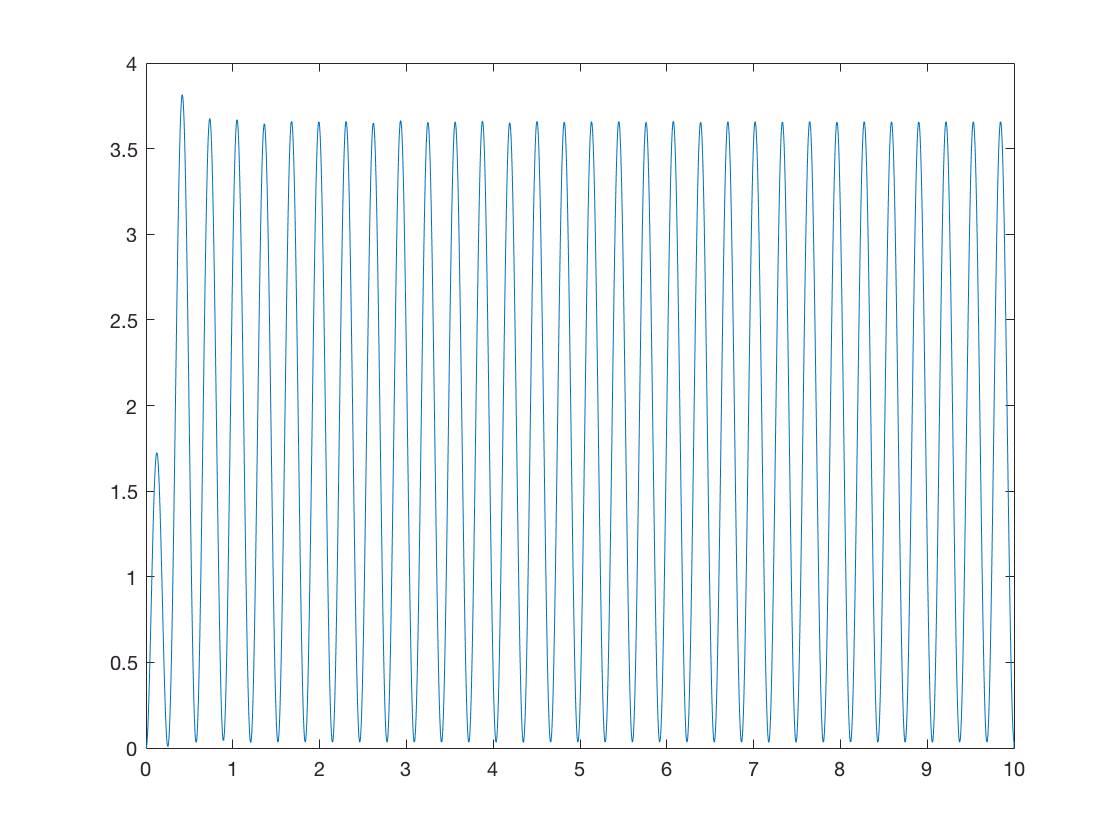


A(20,17:20)=[K(10)/M(10),C(10)/M(10),-(K(10)+K(11))/M(10),-(C(10)+C(11))/M(10)];
while (i<=19)
  A(i,i+1)=1;
  i=i+2;
  
end
while (j<=18)
  A(j,(j-3):(j+2))=[K(j/2)/M(j/2),C(j/2)/M(j/2),-(K(j/2)+K(j/2+1))/M(j/2),-(C(j/2)+C(j/2+1))/M(j/2),K(j/2+1)/M(j/2),C(j/2+1)/M(j/2)];
  j=j+2;

end
for ii=1:20
    W(:,ii)=A^(ii-1)*B;
end
for nn=1:9
    C1(2*nn-1,2*nn-1:2*nn+1)=[1,0,-1];
end
C1(19,17:19)=[1,0,-1];
%A1=A-B*K1;
syms s 
I=eye(20);
adetA=det(s*I-A);
syms e
B1=[130/3;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0];
%adet=det(A1-s*I);
Co=coeffs(adetA,s);
F=1;
for iii=1:20
    F=F*(s+50);
end
Hgen=coeffs(F,s);
K2=zeros(1,20);
A2=zeros(20,20);
B2=zeros(20,1);
B2(1,1)=1;
for jjj=1:20
    K2(jjj)=Hgen(1,21-jjj)-Co(1,21-jjj);
    A2(1,jjj)=-Co(1,21-jjj);
end
for iiii=1:19
    A2(iiii+1,iiii)=1;
end
for jjjj=1:20
    W2(:,jjjj)=A2^(jjjj-1)*B2;
end
w=10;
S=zeros(1,3000);
S2=zeros(1,3000);
x=zeros(20,3000);
dx=zeros(20,3000);
t=0.001:0.001:3;
x(:,1)=zeros(20,1);
for tt=1:2999
   dx(:,tt)=(A*x(:,tt)+B1*0.4*cos((w*t(1,tt))));
   x(:,tt+1)=x(:,tt)+0.001*dx(:,tt);
   sss=(x(1,tt)-x(3,tt))^2+(x(3,tt)-x(5,tt))^2+(x(5,tt)-x(7,tt))^2+(x(7,tt)-x(9,tt))^2;
   ss=(x(9,tt)-x(11,tt))^2+(x(11,tt)-x(13,tt))^2+(x(13,tt)-x(15,tt))^2+(x(15,tt)-x(17,tt))^2+(x(19,tt)-x(17,tt))^2;
   S(1,tt)=ss+sss;
end

for tt=1:2999
   dx(:,tt)=(A3*x(:,tt)+B1*0.4*cos((w*t(1,tt))));
   x(:,tt+1)=x(:,tt)+0.001*dx(:,tt);
   sss=(x(1,tt)-x(3,tt))^2+(x(3,tt)-x(5,tt))^2+(x(5,tt)-x(7,tt))^2+(x(7,tt)-x(9,tt))^2;
   ss=(x(9,tt)-x(11,tt))^2+(x(11,tt)-x(13,tt))^2+(x(13,tt)-x(15,tt))^2+(x(15,tt)-x(17,tt))^2+(x(19,tt)-x(17,tt))^2;
   S2(1,tt)=ss+sss;
end

plot(t,S)

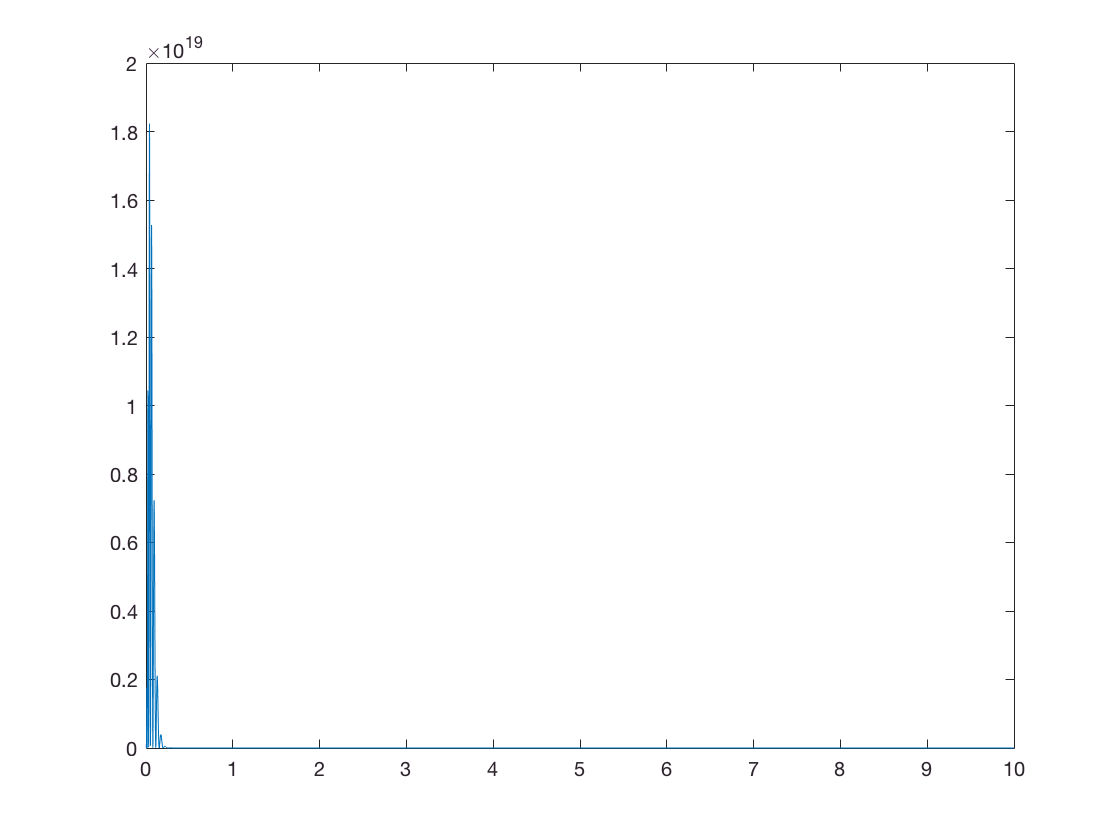

plot(t,S2)